spectral resolution is 1 Hz so the signal has to be T0=1/F0 s long i.e 1/1=1s

clear ylim
% Extract the wanted signal
wanted_duration = 1/spectral_resolution;
nb_samples = round(wanted_duration * fs)

nb_samples = 10000


y = y_long(1:nb_samples)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


t=0:1/fs:wanted_duration-(1/fs);

Same as multiplying by a rect (window) function with ones everywhere where we want to keep the signal, and zeros everywhere else. The cutting will lead to oscilations in the frequencies plots. 


% make the spectrum function 
function [Y, freq] = make_spectrum(signal, fs)
Y = fft(signal); % compute spectrum (note: it will be complex-valued).
Y = abs(Y/(length(signal))); % The FFT needs to be scaled in order to give a physically plausible scaling.

T0=(length(signal))/fs;
delta_f = 1/T0
frequneg= (-fs/2)+delta_f:delta_f:-delta_f;
freqpos= 0:delta_f:fs/2;
freq= [freqpos, frequneg];

Y = Y(:);
freq = freq(:);

end

if window=="rect"
    y=y.*rectwin(length(y))'
elseif window=="hann"
    y=y.*hann(length(y))'
elseif window=="hamming" 
    y=y.*hamming(length(y))'
end

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% Compute the frequency spectra of the signals
[Y, freqs] = make_spectrum(y, fs);

delta_f = 1


%make the magnitude spectra in dB
magnitude= abs(Y);
magnitude_dB= 20*log10(magnitude);

Generated signal:

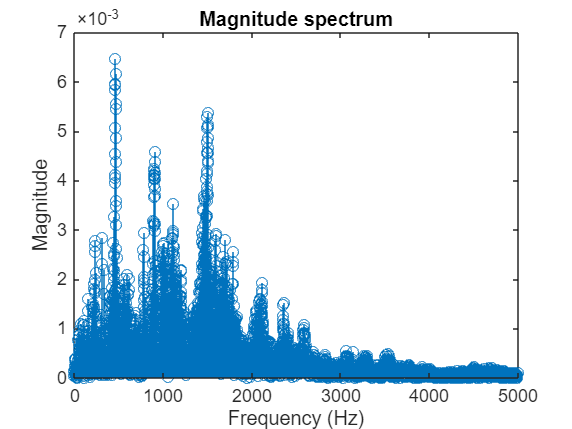

% plot the magnitude 
figure;
stem(freqs, magnitude)
title('Magnitude spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0, xlimFreq])  ;

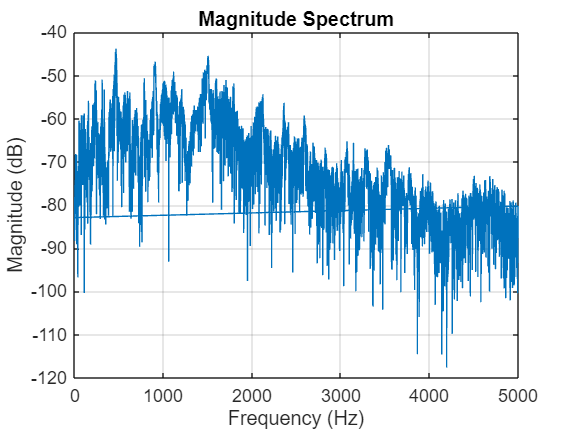

ylim=([-ylimFreq, ylimFreq]);

% Plot the magnitude spectrum in dB
figure;
plot(freqs, magnitude_dB);
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0, xlimFreq])  ;

ylim=([-ylimFreq, ylimFreq]);

y=y_long

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


explain limits: nyquist frequency fs/2

STFT:

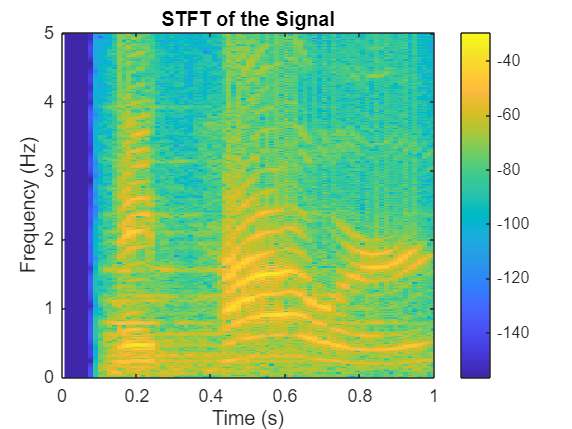

window_length = 256; % Length of each window segment in samples
window_type = rectwin(window_length); % Choose the window type (e.g., hann)
overlap = round(0.5 * window_length); % Set 50% overlap between windows
nfft = 512; % Number of FFT points (determines frequency resolution)

% Perform STFT using spectrogram
figure;
spectrogram(y, window_type, overlap, nfft, fs, 'yaxis');
title('STFT of the Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
xmin = 0;
xmax = wanted_duration; % Use the duration of the extracted signal
xlim([xmin, xmax]);
ylim=([-ylimFreq, ylimFreq]);
colorbar; % Display colorbar for magnitude scaling



%{
% Compute the STFT using spectrogram
[S, F, T] = spectrogram(y, window_type, overlap, nfft, fs); % S is the STFT matrix

% Convert the magnitude to dB (optional)
S_magnitude = abs(S); % Magnitude of the STFT
S_magnitude_dB = 20 * log10(S_magnitude); % Convert to dB (optional)

% Select specific frequencies for line plot
selected_freqs = [100, 200, 300]; % Frequencies of interest (Hz)
idx = zeros(length(selected_freqs), 1); % Initialize index array

% Find the closest frequency indices
for i = 1:length(selected_freqs)
[~, idx(i)] = min(abs(F - selected_freqs(i)));
end

% Check the size of the arrays
disp(['Size of T: ', num2str(size(T))]);
disp(['Size of S_magnitude: ', num2str(size(S_magnitude))]);

% Ensure T and S_magnitude(idx(i), :) have the same number of elements
if length(T) ~= size(S_magnitude, 2)
error('T and S_magnitude(idx(i), :) must have the same number of elements.');
end

% Plot magnitude over time for selected frequencies
figure;
hold on;
for i = 1:length(selected_freqs)
plot(T, S_magnitude(idx(i), :)', 'DisplayName', [num2str(selected_freqs(i)), ' Hz']); % Plot magnitude for selected frequencies
end
hold off;

% Customize plot
title('STFT Magnitude Over Time for Selected Frequencies');
xlabel('Time (s)');
ylabel('Magnitude');
legend show; % Show legend with frequency labels
grid on;
%}


% Custom Spectrogram Function Using Project Variables
function [fs, window_type, window_length, overlapSTFT, nfft] = custom_spectrogram(y)

% Generate the window
switch window_type
case 'hann'
window = hann(window_length);
case 'hamming'
window = hamming(window_length);
case 'rect'
window = rectwin(window_length);
otherwise
error('Unsupported window type.');
end

% Overlap in samples
overlap = round((overlapSTFT / 100) * window_length);

% Initialize variables
step = window_length - overlap; % Step size for sliding window
num_frames = ceil((length(y) - overlap) / step); % Number of frames
freq_axis = (0:nfft-1) * (fs / nfft); % Frequency axis
time_axis = (0:num_frames-1) * (step / fs); % Time axis
spectrogram_matrix = zeros(nfft, num_frames); % Store STFT results

% Compute STFT
for i = 1:num_frames
start_idx = (i-1)*step + 1;
end_idx = min(start_idx + window_length - 1, length(y));
frame = y(start_idx:end_idx);

% Apply the window
windowed_frame = frame .* window;

% Compute FFT
fft_result = fft(windowed_frame, nfft);
spectrogram_matrix(:, i) = abs(fft_result); % Store magnitude
end

% Plot the spectrogram
figure;
imagesc(time_axis, freq_axis, 20*log10(spectrogram_matrix));
axis xy;
title(['Custom Spectrogram of Signal']);
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;
end